# Running Kalman Filter for a Stationary Robot

Objective: This script will show you how  to implement the Kalman Filter for a Stationary Holonomic Robot. You will create a function (*KFStationary)* that runs the Kalman Filter prediction and update step specifically for a stationary robot. You will then use *test_KFStationary* to run the Kalman filter over a time series. 

Helper Functions used in this exercise:

- *plotKF: *This function will create a figure where you can step through the updates to mu and sigma over time. The center of the ellipse is the current guess and the 2 axes of the ellipse indicate the uncertainty in the x and y location

Execise:

In this exercise, we will run the Kalman Filter for robot that has a LIDAR sensor onboard but does not move. The robot will contiously be getting measurements fromt he LIDAR sensors (a simplified LIDAR with 4 angle range measurement readings pi/2 radians apart - similar to that tested in *simulate_LIDAR_sensor_noise*. Using these measurements, we will run the kalman filter to estimate the robot's pose. Because the robot is stationary - this simplifies the Kalman filter implementation because it minimizes the impact of the process noise. 

robotXY = [1.25;1];
map = load ('MAP102M1.txt');
maxRange = 4; % LIDAR max Range
alpha = [pi, pi/2, 0, -pi/2]; %angles for the LIDAR
N = 20; %Number of measurements


**Kalman Filter Initialization**

1) The variable mu should be a 2x1 column vectorand sigma should be a 2x2 matrix. We'll start with a guess of $\mu$ = [-0.8; -0.8]. $\Sigma$ can be initialized to a diagonal matrix with relatively high values (like 2 meters).

**COMPLETE THE CODE BELOW**

mu_value = -.8; %Change value here
mu = [-.1; -.8];  % 2-by-1 vector
sigma_value = 2; %Change value here 
sigma = 2*eye(2);  % 2-by-2 matrix

variance = [0.1 0.3 0.1, 0.3];
Q = diag(variance);

2) Now you need to create the matrix C which relates the measurements to the robot state ($x,y$) according to the equation $z = Cx$ where $z$ is the column vector of measurements and $x$ is the column vector of the robot state. Thus the size of $C$ for this example is 4-by-2 as we have four measurements. 

**COMPLETE THE CODE BELOW**

C = zeros(length(alpha),2);
for i = 1:length(alpha)
    C(i,:) = [-cos(alpha(i)) -sin(alpha(i))]; 
end

**Running the Kalman Filter**

Now we have the inputs, we can loop through the measurements and apply the Kalman Filter iteratively. Make sure all of the inputs are in the correct format.

Set up the 

mu_hist = zeros(2,N+1); 
sigma_hist = zeros(2,2,N+1);
mu_hist(:,1) = mu;
sigma_hist(:,:,1) = sigma;


**COMPLETE THE CODE BELOW**

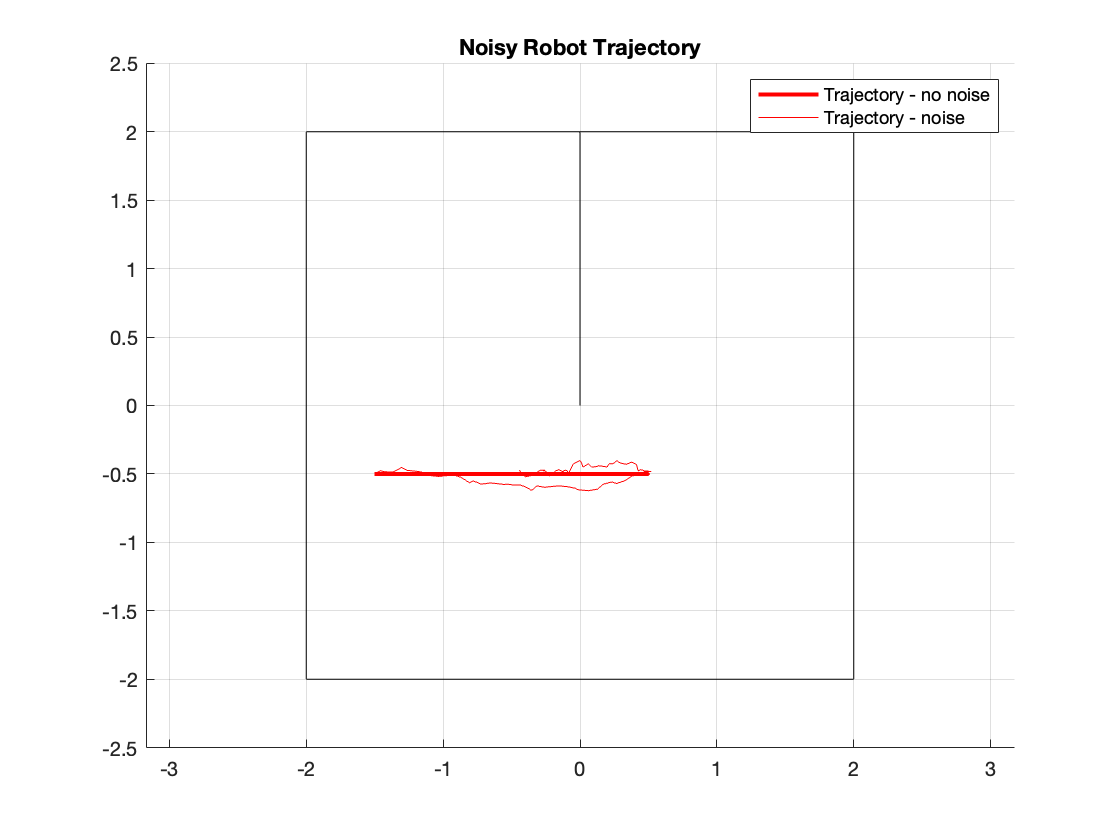

for i = 1:N
    [mu,sigma] = KFStationary(map, measurements(i,:)', mu, sigma, C, Q, alpha, maxRange);
    mu_hist(:,i+1) = mu;
    sigma_hist(:,:,i+1) = sigma;
end

Expected Results: 

Check your Comprehension: Do your results make sense? How accurate is localized position?

To better understand the results:

1) Change the Kalman FIlter initialization parameters for mu, sigma, and Q. How does this alter the resulting localizated position? Given the covariance matrix Q, which axis of the ellipse should be longer? Is that true of the final ellipse (you may have to zoom in)? What happens to the ellipse from the initialized guess to the final estimate?